# Supervised Learning: Classification 

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

In this script, we use supervised classification to train a model that can detect ovarian cancer from blood serum data and known diagnoses.

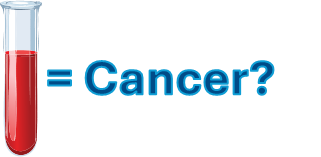

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**. Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The   and  icons refer to two different types of interactive activities that you will find in this script. The   usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## From Data to Diagnosis: Using Supervised Learning to Detect Ovarian Cancer

What if we could detect ovarian cancer from a simple blood test? Machine learning enables this kind of breakthrough. For a refresher on the types of machine learning and its benefits, revisit [An Overview of Machine Learning for Science and Engineering](matlab:open('./IntrotoMachineLearning.mlx')).  

In this script, we will apply **supervised learning**, a method where a model is trained on data that includes both the input and the correct output which in this case are the blood profiles and the corresponding diagnoses. By learning from these labeled examples, the model can identify patterns associated with the presence or absence of disease. Since we are predicting one of two possible outcomes, cancer or no cancer, we will use **classification learning**, which is a type of supervised learning designed to assign inputs to specific categories. Once trained, the model could help analyze new patient samples and support earlier detection and better outcomes.

We will use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to explore our data, select important features, and train our model to distinguish between cancer and non-cancer cases. The [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) provides an interactive and visual way to apply classification algorithms without needing to write code, making it easier to focus on understanding the data and the modeling process. As we go through the project, we will guide you step by step in how to use the app effectively and explain the key concepts behind each action.

### Prepare Data for Machine Learning

To begin, we load and examine the dataset by reviewing its structure, contents, and dimensions. This step helps us understand what each patient sample represents and the amount of information contained within it. By familiarizing ourselves with the data early on, we set the stage for applying unsupervised learning techniques that can help us distinguish between patients with and without ovarian cancer.

  **Try.** Load and format the data for machine learning. Learn more about the LoadOvarian function [here](matlab: doc LoadOvarian).

 
Preview = false;
Help = false;
[OvarianInputs, OvarianTargets] = LoadOvarian(Preview,Help); % Live function to import data and format data into tables

#### Create One Data Table

To train our model, we need to provide the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) with both the input data and the corresponding labels, or diagnoses. We will create a new table by combining `OvarianInputs` with `ovarianTargets`. Since each label is a binary vector of [1;0] for cancer and [0;1] for healthy, we only need one column of `ovarianTargets` to represent the diagnosis. Including both would be redundant, as one value implies the other. Adding this single label column to the 100 features, ion intensity levels in `OvarianInputs` gives us a complete table with 216 rows and 101 columns, ready for training in the app.

  **Try.** Append the ovarian dataset to include the response data.

 
OvTable = OvarianInputs;
disp("Dataset appended.")
OvTable.Cancer = OvarianTargets.Cancer % Add OvarianTargets as the last column to OvTable

## Get Started with the Classification Learner App

We will use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to do **supervised learning** on our data set. Before we open the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html), let's look at the interface and get acquainted with it. After we load our data set, we will see a user interface with two distinct sections: data set and validation. 

In the New Session from Workspace dialog box, under **Data Set Variable**, we can select columns or rows as our variable. In the **Data set** section, the **Data Set Variable** section shows the data set you have loaded. In the next section, under **Response**, we can select a response variable from the data set variable or from the workspace.  Under **Predictors**, your loaded data set is listed in a spreadsheet. You can scroll through the data set here. The Name, Type, and numeric Range are column headers. 

In the **Validation **section, we can choose a validation scheme to assess performance and further specify parameters of the chosen scheme. In the **Test** section, we can optionally choose to set aside a percentage of our test data set to use to validate our trained model. 

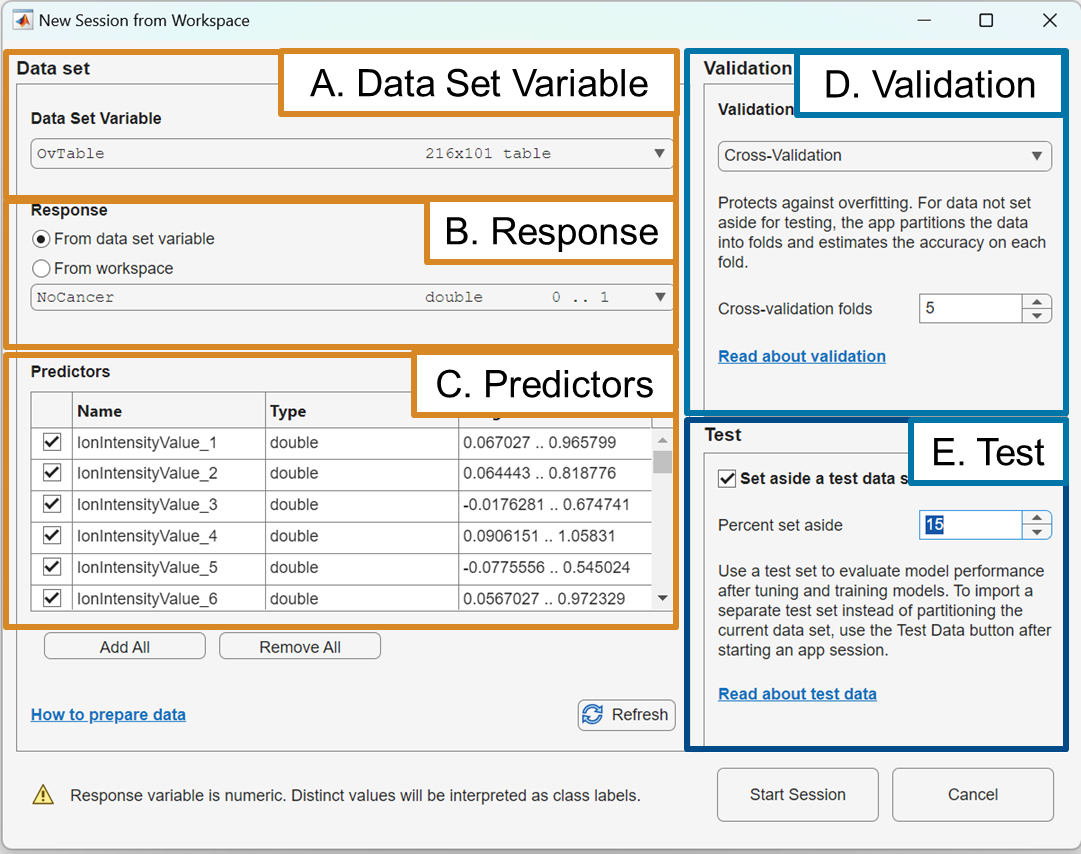

### Open Classification Learner App

  **Try. **Let's get started loading data into the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html).

 
classificationLearner 

### Select Data

Once the **Classification Learner App** opens, follow the steps below.

- On the **Learn** tab, in the **File** section, click **New Session** and select data from the workspace or from a file. 

- In the New Session from Workspace dialog box, under **Data Set Variable**, select  O`vTable `from the workspace variables.

- Check the **Set aside a test data set **box.

- Adjust the Percent set aside to 15.

- Click **Start Session** to accept the default validation scheme and continue.

- A new window will open and you will see a column titled **Models**, and a **scatter plot** similar to the one below. 

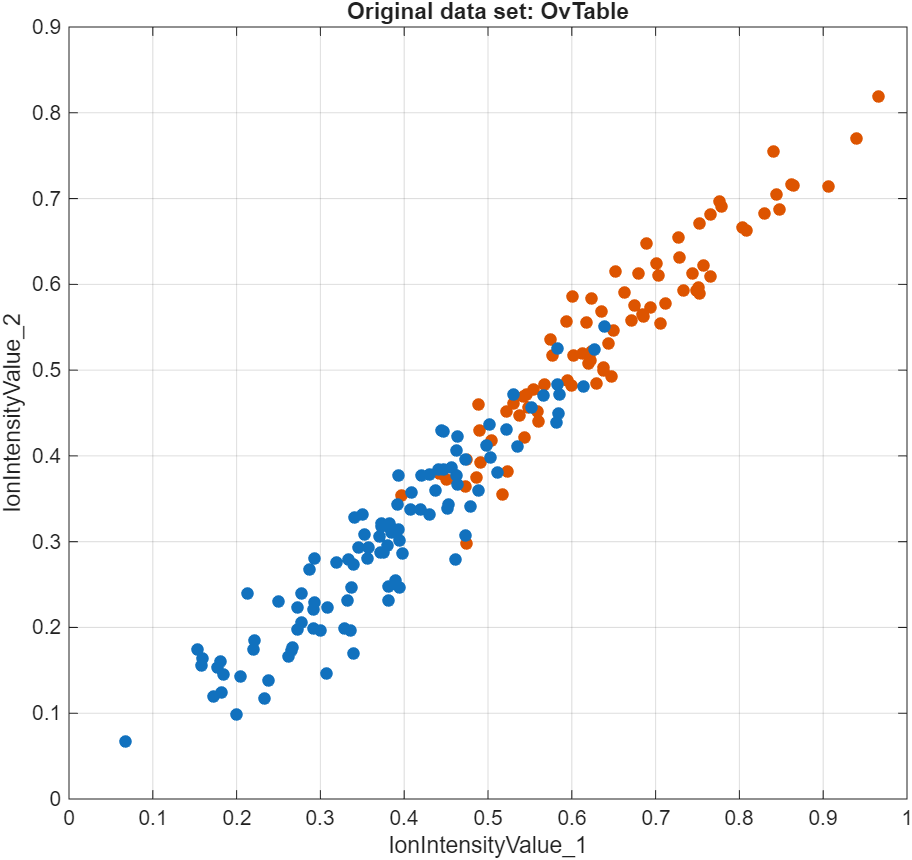

### Train the Model

After the **scatter plot** has appeared, you can begin to train your model. There are eleven different training models that are quick to train, so we will choose the **All Quick-To-Train** option and then train the data on all of these models.

- In the **Models** section of the toolstrip, select **All Quick-To-Train **icon. 

- In the **Train** section, click **Train All** and select **Train All**.

When using the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html), you might notice that your results differ slightly from what is shown as sample outcomes. The randomness of outcomes is expected because by default, [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) prevents overfitting, by holding back a portion of the data for validation or testing. This process involves random sampling, which introduces variability. Additionally, some machine learning algorithms include random elements, such as how data is split or how models are initialized, which can lead to slightly different outcomes each time you train. The example results are meant to give a general idea of what to expect rather than serve as an exact match.

During training, this variability becomes evident in the results you observe. The training can take up to 5 minutes because the all quick to train option trains the data on eleven different training models. You will see two outcomes: a list of the **models** tested along with their accuracy on the left, and a **Validation Confusion Matrix** on the right. For each model trained, the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) will generate the Name of the model, the **accuracy (validation)** percentage, and an accounting of the number of features tested. The confusion matrix is a table used to evaluate the performance of a classification model. It compares the predicted labels from the model with the actual labels from the data. In the confusion matrix, the rows represent the actual or true classes and the columns represent the predicted classes. Along the diagonal, where you have 0 for the true and predicted class and 1 for the true and predicted class, you have the true negatives and true positives respectively. 

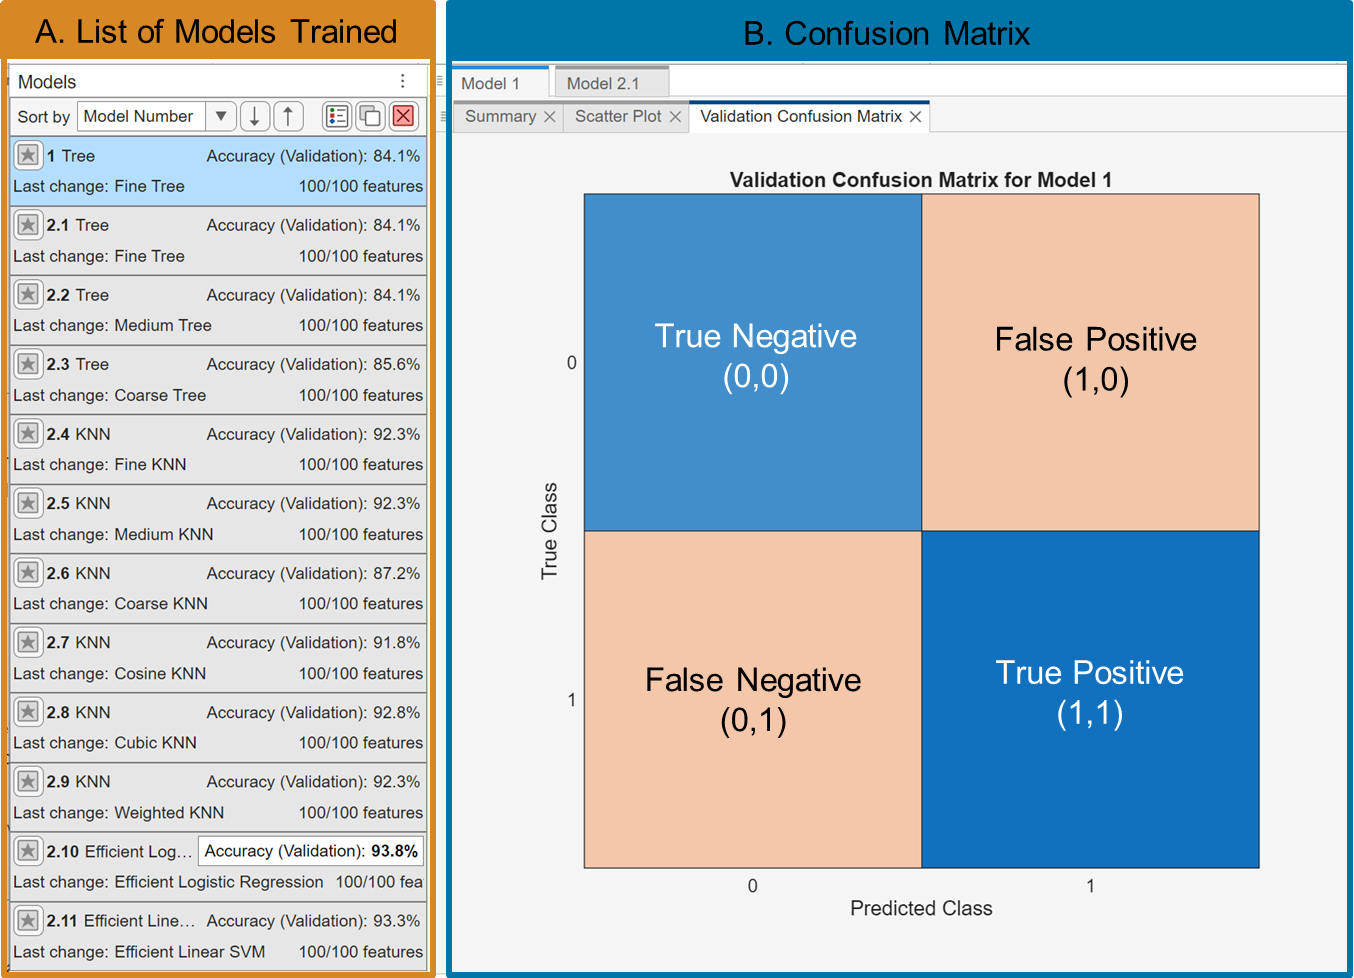

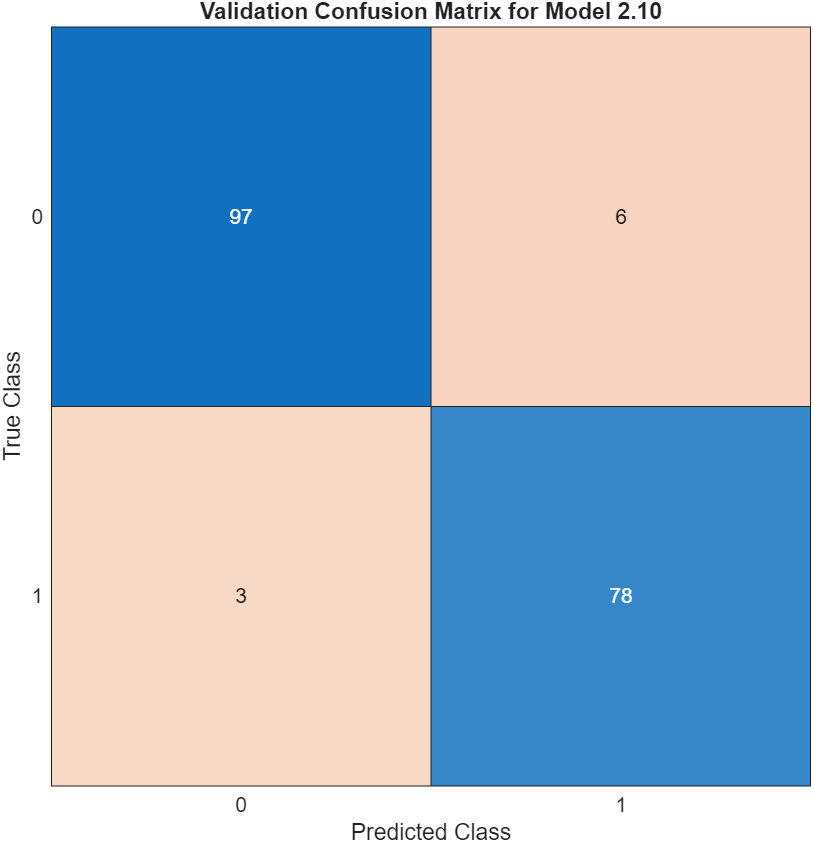

 **Exercise 1. **Based on the confusion matrix above, how many false positives of cancer have been diagnosed?

**Solution:**

CheckAnswer("Exercise1","");  

### Test the Model

After training 11 models, we see the most accurate models or the ones where the accuracy is the percentage of observations that are classified correctly. Because we know the most accurate model from the section above, we will only use a limited set of models. We can do this by manually sorting the models based on **Accuracy (Validation)**. We can do this by going to the 'Sort by' dropdown menu below the Models and selecting Accuracy (Validation). We will then choose the down arrow . 

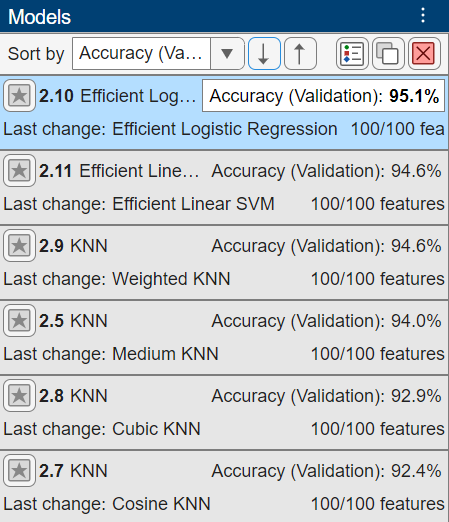

At the start of our process, we set aside 15% of the dataset, which has not been used in any training or validation steps, thereby leaving this data completely unseen by the model.

We are now ready to evaluate the model on this unseen data. The key question is: **How well does the model perform on data it has never encountered before?** When we relate this question to our initial problem statement, how well will this model be able to predict cancer from blood serum levels?

### Compare Classification Models

- Go to the **Test** tab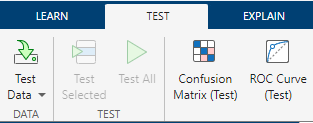.

- Select the first accuracy model, which should be your highest accuracy model from the previous step.

- Select the **Test Selected** icon 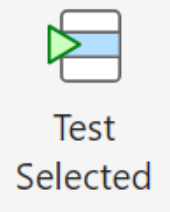 under the **Test** tab of the toolstrip to test the new data.

- Select the **Results Table** icon 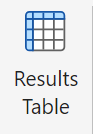 under the** Plots and Results **tab of the toolstrip to view the testing results.

You will see a results table similar to the one below:

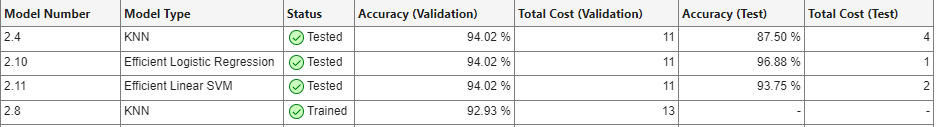

### Improve the model

To optimize our model for detecting ovarian cancer from blood serum data, we will tune three parameters that directly impact our ability to achieve accurate and meaningful results. Recall, we are working with 100 features or **ion** markers. We don't know which features are relevant and impact our model, so we will use **feature selection** to identify the most influential ones. This allows the model to focus on the features that carry the strongest signals related to cancer, helping reduce noise and improve performance. 

In addition, we are working with multidimensional data, and we can capture the most important patterns in the data with fewer dimensions by doing **Principal Component Analysis (PCA).** This helps simplify the data while preserving the variation that may be most relevant to distinguishing between healthy and cancerous profiles. Furthermore, in our first attempt, we assigned equivalent miscalculation costs, but we don't want to run the risk of too many false negatives, so we will increase the penalty for misclassifying the false negative class. This is important because in the context of cancer detection, missing a positive case can have serious consequences. By adjusting **classification costs**, we can guide the model to prioritize sensitivity, which is critical for early and reliable detection.

After you train a model, the **Feature Selection** section of the model **Summary** tab lists the features used to train the full model.

#### 1. Feature Selection

- Make a copy of your preferred (best-results) model by right-clicking on the model in the **Models** section. You will see a menu pop-up with three options. Select the **duplicate** option 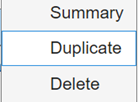.

- A draft copy of the duplicate will open. 

- Select 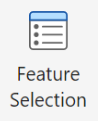 from the toolstrip on the **Learn** tab.

- Under **Feature Ranking Algorithm**, select Chi2,  or chi-squared, which ranks the features in terms of their importance for prediction as a feature ranking algorithm. 

- We will see a features vs. importance score bar plot, which gives us a visual representation to help us determine how influential different features are in our model. This plot is similar to the Scree plot discussed in [Unsupervised Learning.](matlab:open('./UnsupervisedLearning.mlx')) 

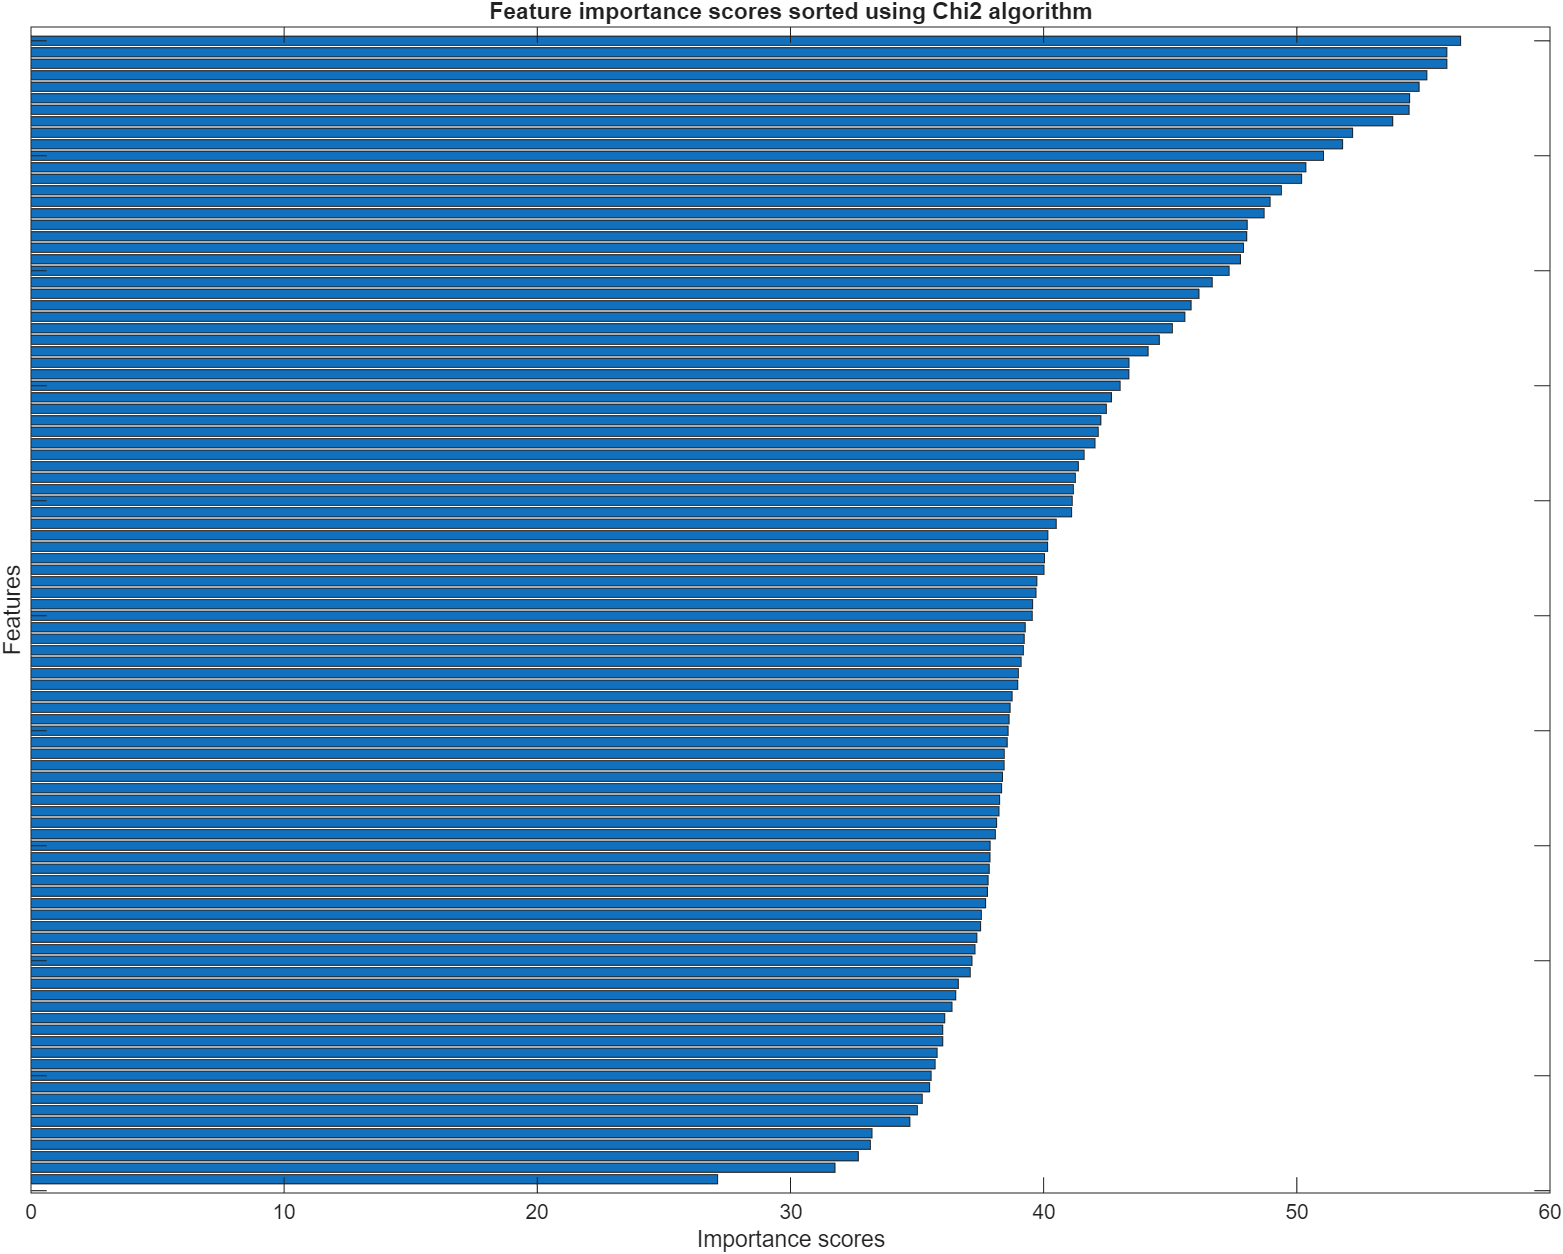

       6. There are several strategies to select features that are beyond the scope of this lesson. Here, we will use the top-k selection strategy to obtain a fixed number of features for modeling, and we will pick the top 20 features by typing "20" into **Num features to keep **and then select the Save and Apply button. 

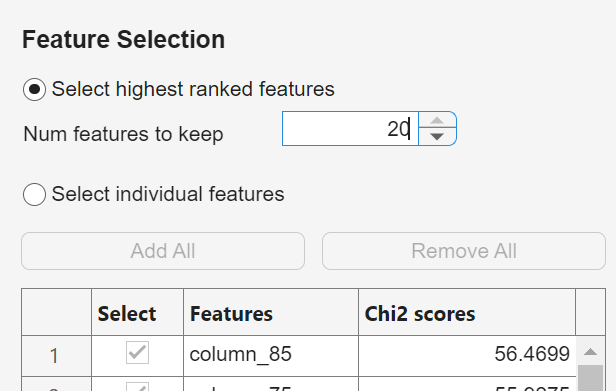

#### 2. PCA

Under the **Options** tab of the Toolstrip, select the PCA option. A pop-up of Default PCA Options will appear. Select the checkbox to enable PCA and then select Save and Apply.

 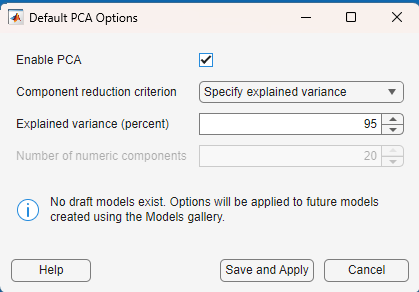

Recall from [Unsupervised Learning](matlab:open('./UnsupervisedLearning.mlx')) that PCA allows us to reduce the dimensions of our data while still holding the most important data (**reword this**). So with PCA, we look for the dimensions that explain 95% of the dataset. 

#### 3. Misclassification Costs

< Add something about wanting to avoid false negatives>

The total cost of the test is by default assigned as the number of misclassified observations. Having cancer is category "1" and a non-cancer diagnosis is "0". We want to minimize the number of people who are told they don't have cancer, the predicted class 1, but have cancer, the true class 0, to be minimized, or the number of false negatives, so we can double the cost of category 1 being predicted as category 0. Refer to the example confusion matrix.

To modify costs, we select the  from the **Options** section of the toolstrip. A pop-up *should* open up a new editable window titled, Default Misclassification Costs. Click inside the table, and adjust the lower left box (0,1) to 2 as shown below, and then select the Save and Apply Button

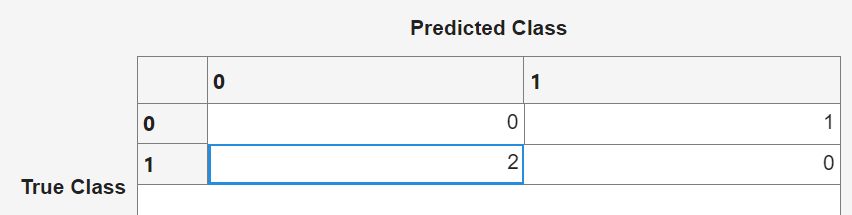

< Add exercise: which cell is the one to change?>

Your Summary page should look like the one below: 

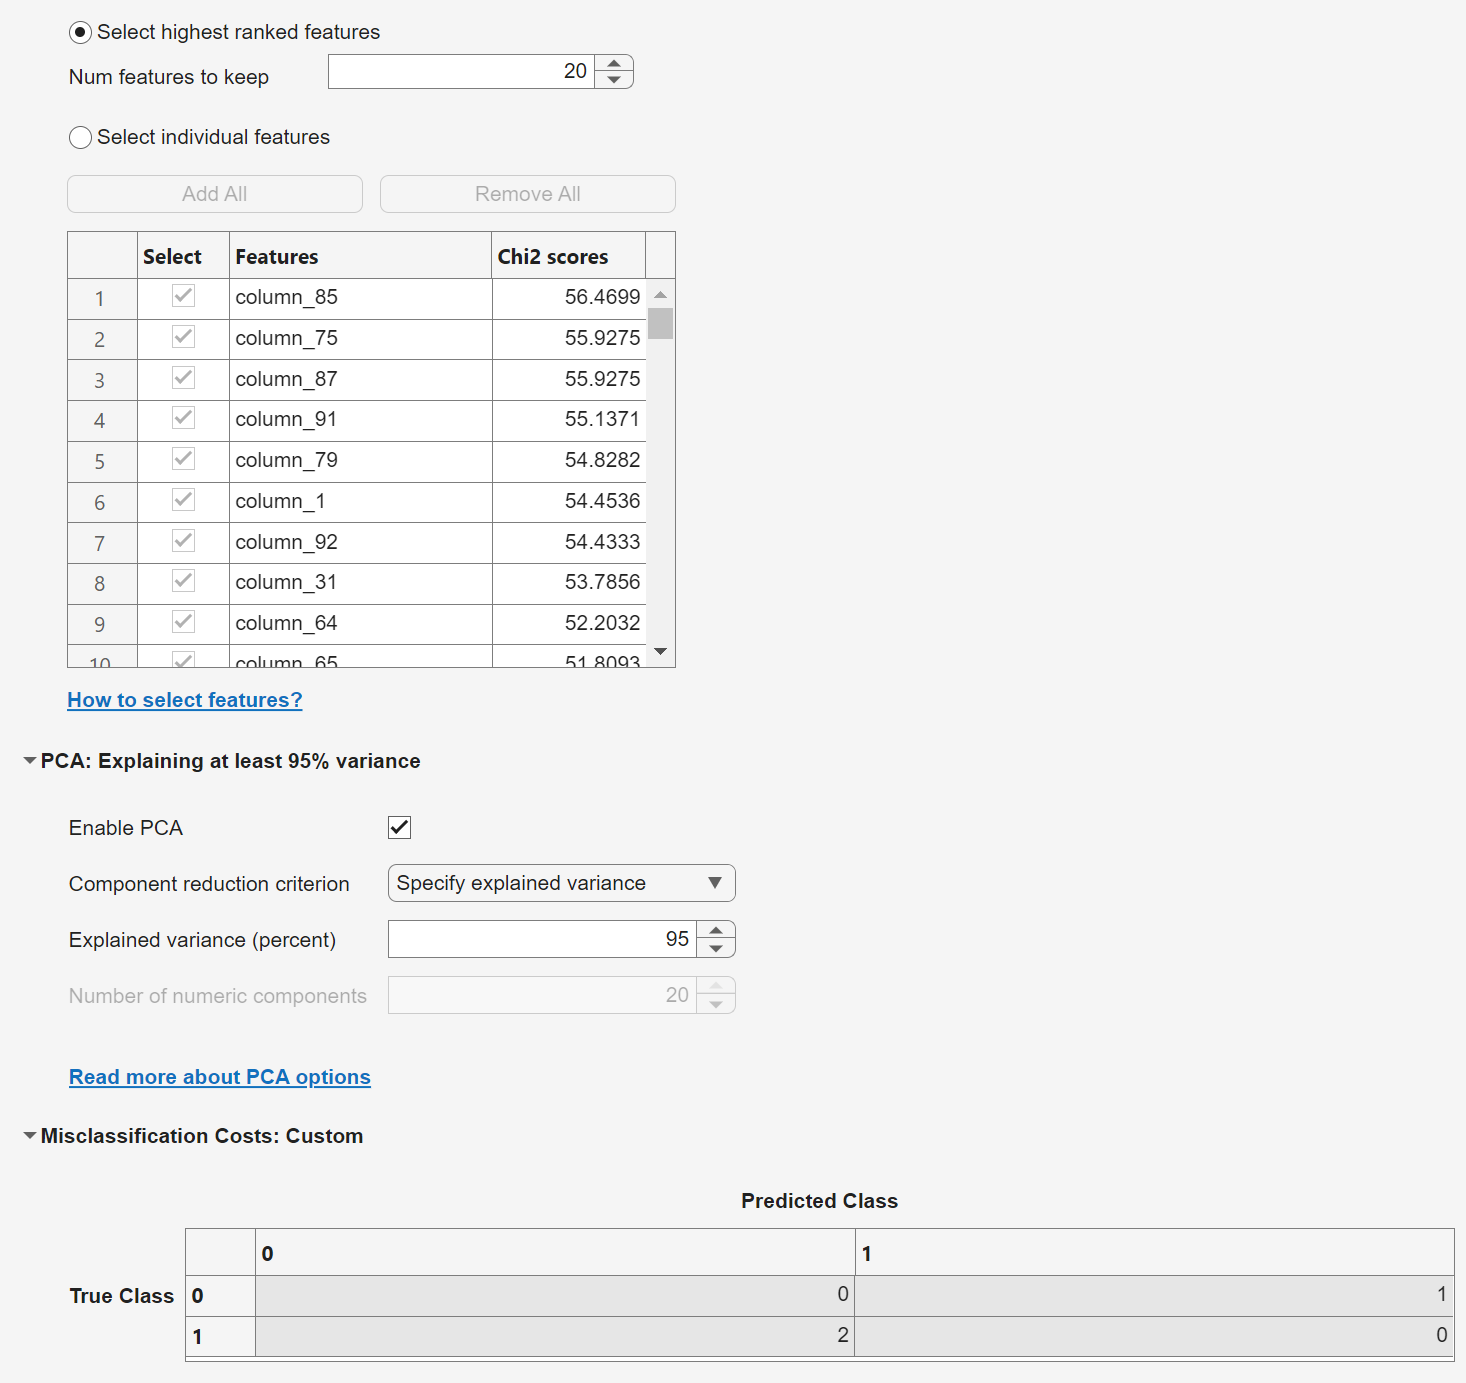

Return to the **Learn** tab and select **Train Selected** to generate new test results.

### Check the Receiver Operating Characteristic (ROC) curve

The ROC curve shows the true positive rate (TPR) versus the false positive rate (FPR) for different thresholds of classification scores, computed by the currently selected classifier. The **Model Operating Point** shown by the dot on each curve shows the false positive rate and true positive rate corresponding to the threshold used by the classifier to classify an observation. For example, a false positive rate of 0.1 indicates that the classifier incorrectly assigns 10% of the negative class observations to the positive class. A true positive rate of 0.85 indicates that the classifier correctly assigns 85% of the positive class observations to the positive class. If the model's ROC curve hugs the top-left corner, it means there is a high TPR, which means the model caught most of the true positives, and there were few false alarms. This is our ideal classification scenario. 

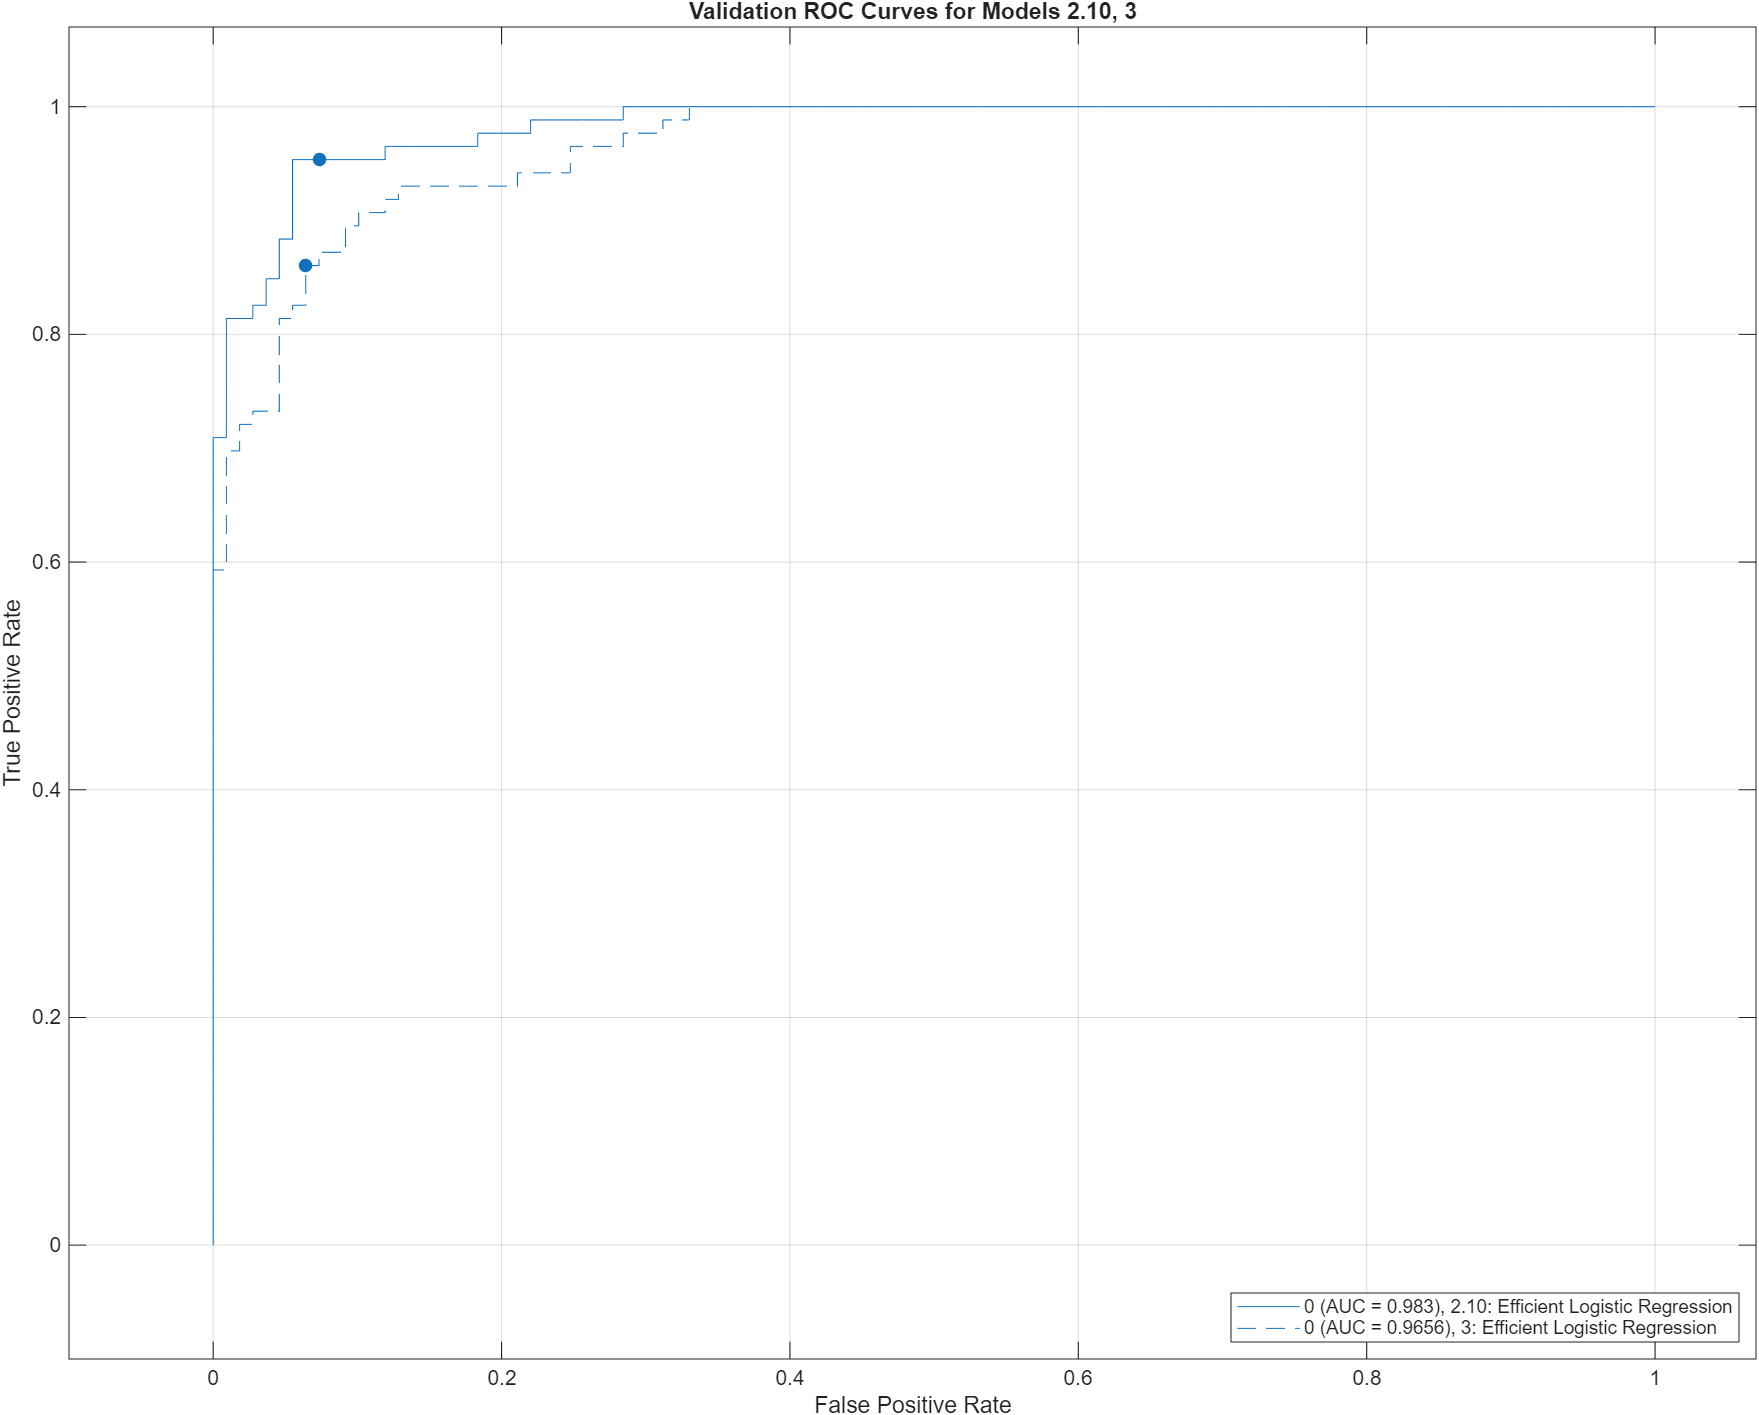

## Further Exploration

Explore the documentation to learn more about using the [Classification Learner App](https://www.mathworks.com/help/releases/R2025a/stats/classificationlearner-app.html) to perform supervised learning. 

- [**Train Classification Models in Classification Learner App**](https://www.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html)

- [**Visualize and Assess Classifier Performance in Classification Learner**](https://www.mathworks.com/help/stats/assess-classifier-performance.html)

- [**Feature Selection and Feature Transformation Using Classification Learner App**](https://www.mathworks.com/help/stats/feature-selection-and-feature-transformation.html)

- [**What is a ROC Curve?**](https://www.mathworks.com/discovery/roc-curve.html?s_tid=srchtitle_site_search_1_ROC+curve)

## Glossary

**Classification learning: **A supervised learning task where the goal is to predict discrete labels or categories, such as identifying an image as a "cat" or "dog. (↑ Return to Text)

**Supervised** **learning: **A type of machine learning where the model is trained on labeled data to learn the relationship between inputs and known outputs. (↑ Return to Text) 

[⇦ Return to the main menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckAnswer(exerciseID, option) % Function to check answers for exercises
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
   "Exercise1",struct("Answer","6","hint","False positives happen when the model predicts cancer(1) but the true class is non-cancer(0).")...
      );
% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).Answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.")
    elseif isequal(option,"Select")
        warning("Select a valid option.")
    else
        warning("%s",hint)
    end
else
    warning("Exercise not found.")
end
end